### Pre-requisites

Computer Vision Toolbox *with Image Processing Toolbox*

foldername = "16_08_5";
valid_files = dir(foldername + "\*.tif");...
        dir(foldername + "\*.png")

No matches for pattern '16_08_5\*.png'.



images = []


images =

     []



interpolation = 0.5; % scaling factor of the new image

for i = 1:length(valid_files)
     images(:,:,:,i) = imresize(imread(foldername+"\"+valid_files(i).name),interpolation,'bicubic');
end

reference = images(:,:,:,23)

reference = reference(:,:,1) =

    19    19    18    19    17    17    19    17    17    19    19    19    19    19    19    19    19    19    17    19    19    19    19    19    20    19    20    19    19    19    19    20    20    20    20    20    20    19    19    19    18    20    20    21    20    20    21    20    20    21    20    21    21    19    20    20    20    20    21    23    21    20    21    21    20    20    22    21    23    23    21    21    22    21    22    21    21    21    21    21    22    23    23    22    24    23    22    22    23    23    22    22    22    24    22    22    24    24    24    24    24    24    24    25    24    25    24    25    24    25    25    24    24    24    25    24    25    26    25    24    25    25    25    25    26    26    26    26    26    26    28    26    26    26    26    26    26    26    28    28    28    26    26    28    27    29    29    29    29    27    29    28    27    28    26    29    27    27    29    28    29  

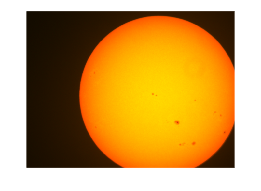


%colorThresholder(reference) % can this be used to produce the right mask ? 

imshow(uint8(reference)) % reference image

tracking_method = 'circle'; % other options "crosscor" and "peak";

peaks = []


peaks =

     []

